## **1. CoppeliaSim Initialization**

clear all; clc; close all;

sim = remApi('remoteApi');

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


sim.simxFinish(-1);
id = sim.simxStart('127.0.0.1', 19000, true, true, 5000, 5);

if id < 0
    disp('Connection failed!')
    sim.delete;
    sim_run_flag = 0;
    return;
else
    fprintf('Connection %d to remote API server is open!\n', id);
    [~, right_motor] = sim.simxGetObjectHandle(id, '/PioneerP3DX[0]/rightMotor',sim.simx_opmode_blocking);
    [~, left_motor] = sim.simxGetObjectHandle(id,'/PioneerP3DX[0]/leftMotor',sim.simx_opmode_blocking);
    [~, pioneer_p3dx] = sim.simxGetObjectHandle(id,'/PioneerP3DX[0]',sim.simx_opmode_blocking);
    [~, bill] = sim.simxGetObjectHandle(id,'/Bill[4]',sim.simx_opmode_blocking);
    for i = 1:5
        [~, disc{i}] = sim.simxGetObjectHandle(id, ['/Disc[', num2str(i-1), ']'], sim.simx_opmode_blocking);
    end
    
    for i=1:1:16
        [~,sensor(i)]=sim.simxGetObjectHandle(id, ['/PioneerP3DX[0]/ultrasonicSensor[', num2str(i-1), ']'], sim.simx_opmode_blocking);
    end

    for i=1:1:16
        [~,detect(i),distance(i,:),~,~]=sim.simxReadProximitySensor(id, sensor(i),sim.simx_opmode_streaming);
    end

    ret_codeR = sim.simxSetJointTargetVelocity(id, right_motor, 0.0, sim.simx_opmode_streaming);
    ret_codeL = sim.simxSetJointTargetVelocity(id, left_motor, 0.0, sim.simx_opmode_streaming);
    sim_run_flag = 1;
end

Connection 0 to remote API server is open!


## 2. Path Planning

#### Build the map

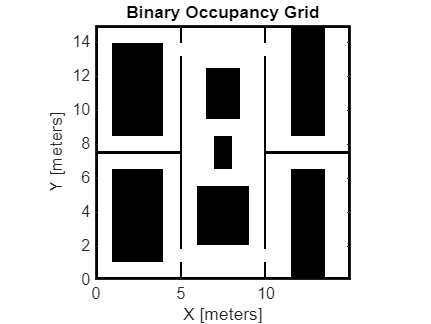

im_map = imread('Office-map.jpg');
im_bin = im2bw(im_map);
myMaplogical = not(logical(im_bin));
map = binaryOccupancyMap(myMaplogical, 433.0667);
show(map);

disp(map.DataSize)

        6496        6496



#### Build 

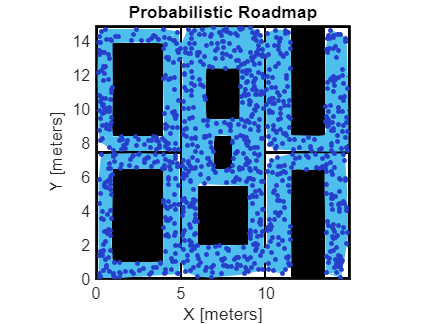

PRM = mobileRobotPRM(map, 1000);
show(PRM);

#### Find Path

if (sim_run_flag == 1)
    [~, pos]=sim.simxGetObjectPosition(id, pioneer_p3dx, -1, sim.simx_opmode_blocking);
    startPositionCoppelia = pos(1, 1:2);
    targetGoal = 5
    for i = 1:targetGoal
        [~, room{i}]=sim.simxGetObjectPosition(id, disc{i}, -1, sim.simx_opmode_blocking);
        roomPositionCoppelia{i} = room{i}(1, 1:2);
    end

end

targetGoal = 5

   14.2876   14.3733



    {[14.2250 9.3750]}    {[1.3750 14.5250]}    {[6.9750 0.5000]}    {[8.0250 0.4750]}    {[9.0500 7.3750]}



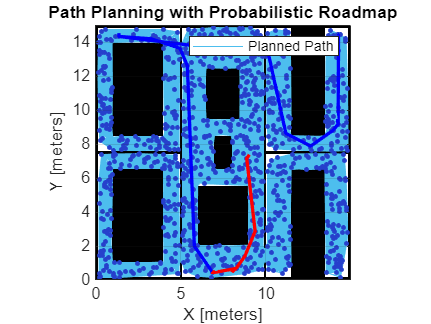


if (startPositionCoppelia == roomPositionCoppelia{1})
    disp(startPositionCoppelia);
    disp('Localization failed');
    sim_run_flag = 0;
else
    % Robot to People
    disp(startPositionCoppelia);
    disp(roomPositionCoppelia);
    pathGoal{1} = findpath(PRM, double (startPositionCoppelia), double (roomPositionCoppelia{1}));
    pathGoal{2} = findpath(PRM, double (roomPositionCoppelia{1}), double (roomPositionCoppelia{2}));
    pathGoal{3} = findpath(PRM, double (roomPositionCoppelia{2}), double (roomPositionCoppelia{3}));
    
    % Gabungkan jalur-jalur menjadi satu
    paths = {pathGoal{1}, pathGoal{2}, pathGoal{3}};
    completePath = [];

    for i = 0:length(paths)-1
        if ~isempty(paths{i+1}) % Adjusting index to access elements of the array
            % Gabungkan jalur, hindari duplikasi titik pertemuan
            if isempty(completePath)
                completePath = paths{i+1};
            else
                completePath = [completePath; paths{i+1}(2:end, :)];
            end
        else
            error(['No path found for segment ' num2str(i)]);
        end
    end
    % Robot to Homebase
    pathGoal{4} = findpath(PRM, double (roomPositionCoppelia{3}), double (roomPositionCoppelia{4}));
    pathGoal{5} = findpath(PRM, double (roomPositionCoppelia{4}), double (roomPositionCoppelia{5}));
    
    % Gabungkan jalur-jalur menjadi satu
    pathsHomebase = {pathGoal{4}, pathGoal{5}};
    completePathHomebase = [];

    for i = 1:length(pathsHomebase)
        if ~isempty(pathsHomebase{i}) % Adjusting index to access elements of the array
            % Gabungkan jalur, hindari duplikasi titik pertemuan
            if isempty(completePathHomebase)
                completePathHomebase = pathsHomebase{i};
            else
                completePathHomebase = [completePathHomebase; pathsHomebase{i}(2:end, :)];
            end
        else
            error(['No path found for segment ' num2str(i)]);
        end
    end

    % Menambahkan plot jalur perencanaan pergerakan ke dalam grafik
    hold on;
    plot(completePath(:,1), completePath(:,2), 'b-', 'LineWidth', 2);
    plot(completePathHomebase(:,1), completePathHomebase(:,2), 'r-', 'LineWidth', 2);
    hold off;
    title('Path Planning with Probabilistic Roadmap');
    legend('Planned Path');
    grid on;
end

## Path Tracking

if (sim_run_flag == 1)
    disp('Simulation is running');

####            Set the Pure Pursuit Control

    pp = controllerPurePursuit;

####            Init  goal reached status

    goalReachedCount = 0;
    reachedGoal = 0;
    count = 0;
    pathPlanning = 0;
    while goalReachedCount<3
        if(pathPlanning == 0)
            pp.Waypoints = completePath;
        end
        if(pathPlanning == 1)
            pp.Waypoints = completePathHomebase;
        end

####                   Get position and orientation of robot (Pose Sensing)

        [~, pos0]=sim.simxGetObjectPosition(id,pioneer_p3dx,-1,sim.simx_opmode_blocking);
        [~, ori]=sim.simxGetObjectOrientation(id,pioneer_p3dx,-1,sim.simx_opmode_blocking);
        [~, oriBill]=sim.simxGetObjectOrientation(id,bill,-1,sim.simx_opmode_blocking);
        currentPositionCoppelia = pos0(1,1:2);     
        currentOrientationCoppelia = ori(1,3);
        currentPoseCoppelia = [currentPositionCoppelia currentOrientationCoppelia];
        referenceOrientationPerson = oriBill(1,3); 

####                   Calculate the velocity of robot (Pure Pursuit)

        [v,w] = pp(currentPoseCoppelia);            

####                    Calculate the angular velocity for right and left wheel of robot (Inverse Kinematics)

        [phiR, phiL] = invkinem(v,w);

                    **Braitenberg Formula Calculation**

        point = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1];
        noDetectionDist=0.2;
        maxDetectionDist=0.1;
        detect=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
        braitenbergL=[-0.2 -0.4 -0.6 -0.8 -1.0 -1.2 -1.4 -1.6 0 0 0 0 0 0 0 0];
        braitenbergR=[-1.6 -1.4 -1.2 -1.0 -0.8 -0.6 -0.4 -0.2 0 0 0 0 0 0 0 0];
        
        for i=1:1:16
            [ret,detect(i),distance(i,:),~,~]=sim.simxReadProximitySensor(id, sensor(i),sim.simx_opmode_buffer);
            if(detect(i)==0)
                point(i)=1;
            else
                point(i)=norm(distance(i,:));
            end
        end

        for i=1:1:16
            distances=point(i);
            if(distances<noDetectionDist)
                if(distances<maxDetectionDist)
                    distances=maxDetectionDist;
                end
                    detect(i)=1-((distances-maxDetectionDist)/(noDetectionDist-maxDetectionDist));
            else
                detect(i)=0;
            end
        end

                    **Velocity Normalization**

        vnorm = 1.25;
        vmax = max(phiR, phiL);
        
        if(any(point < noDetectionDist))
            vright=vnorm + (braitenbergR(1)*detect(1)) + (braitenbergR(2)*detect(2)) + (braitenbergR(3)*detect(3)) + (braitenbergR(4)*detect(4)) + (braitenbergR(5)*detect(5)) + (braitenbergR(6)*detect(6)) + (braitenbergR(7)*detect(7)) + (braitenbergR(8)*detect(8));
            vleft=vnorm + (braitenbergL(1)*detect(1)) + (braitenbergL(2)*detect(2)) + (braitenbergL(3)*detect(3)) + (braitenbergL(4)*detect(4)) + (braitenbergL(5)*detect(5)) + (braitenbergL(6)*detect(6)) + (braitenbergL(7)*detect(7)) + (braitenbergL(8)*detect(8));    
            %This is the correct algorithm, 
            %but for some reason I try not to add up the Breitenberg constant and the detect variable
            %for i=1:16 
            %        vright=vnorm+braitenbergR(i)*detect(i);
            %        vleft=vnorm+braitenbergL(i)*detect(i);    
            %end
        else
            if vmax > vnorm
                vright = ((vnorm / vmax) * (phiR));
                vleft = ((vnorm / vmax) * (phiL));
            else
                vright = phiR;
                vleft = phiL
            end
        end
        

####                   Calculate the final angular velocity of robot wheels (Final Wheel Velocity Decision)

        goalPositionPeople = roomPositionCoppelia{3};
        distToGoalPeople = sqrt((currentPositionCoppelia(1)-goalPositionPeople(1))^2 + (currentPositionCoppelia(2)-goalPositionPeople(2))^2);

        goalPositionHomebase = roomPositionCoppelia{5};
        distToGoalHomebase = sqrt((currentPositionCoppelia(1)-goalPositionHomebase(1))^2 + (currentPositionCoppelia(2)-goalPositionHomebase(2))^2);
        
        if distToGoalPeople < 0.25 && pathPlanning == 0 
            vleft = 0.2 * (referenceOrientationPerson - currentOrientationCoppelia);
            vright = 0.2 * (referenceOrientationPerson + currentOrientationCoppelia);
            count = count+1;
        end
        
        if(count > 100)
            pathPlanning = 1;
        else
            pathPlanning = 0;
        end

        if distToGoalHomebase < 0.25 && pathPlanning == 1 
            vleft = 0;
            vright = 0;
        end
        
        velocity = [count, vleft, vright]
        disp(velocity);

####                   Send the final angular velocity of robot wheels to Pioneer P3DX  (Pioneer P3DX Robot)      

        ret_codeR = sim.simxSetJointTargetVelocity(id, right_motor, vright * 2, sim.simx_opmode_streaming);
        ret_codeL = sim.simxSetJointTargetVelocity(id, left_motor, vleft * 2, sim.simx_opmode_streaming);                        
    end 
    disp('Goal has been reached')
    sim.simxFinish(id);
end
sim.delete(); % call the destructor! 
if (sim_run_flag == 1)
    beep;
    disp('Simulation successful');
else
    beep;pause(1);beep;
    disp('Simulation unsuccessful');
end
disp('Program ended');  

## Functions Definition

function [pR,pL] = invkinem(v,w)
% INVKINEM Inverse kinematics for Pioneer P3DX Diffrerential Steering Robot
    wheelradius = 0.195/2;
    bodywidth = 0.381;
    R2 = wheelradius/2;
    RB = wheelradius/bodywidth;
    vw = [v;w];
    kinemat = [R2 R2; RB -RB];
    pLR = kinemat\vw;
    pR = pLR(1);
    pL = pLR(2);
end